clear
tic ;
% Initial conditions in terms of variable names appearing in the ODE

global N ;
%global Nsim ;
N=4; Nsim=1;

global count;
count = 69;
global y0;
global acc;
acc = [];


    
null = {sprintf('COUNT = %d', count)};
label = {'phi1', 'phi2', 'phidot1', 'phidot2', 'swing', 'swingdot'}

label = 1×6 cell array
    {'phi1'}    {'phi2'}    {'phidot1'}    {'phidot2'}    {'swing'}    {'swingdot'}


isim = 1

IC =          0
    1.5708
    3.1416
    4.7124


IC =          0
    1.5708
    3.1416
    4.7124


ts = 10000

ans =         5569           4


FolderName = 'D:\Courses\2-2\SOP\Data\xls_data\N=4\0.330000'

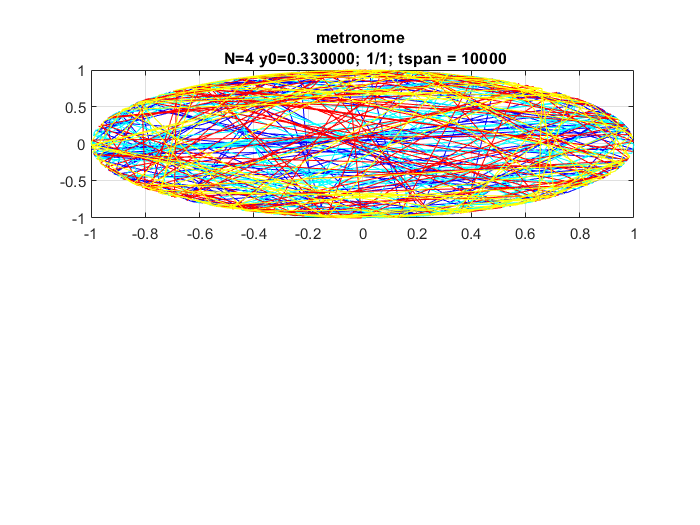


for isim=1:Nsim % Nsim is no.of simulations each with different init cond
    isim
    %IC = zeros(5,1);
   % IC=[-1.5046 ; 0.6268 ; -0.1304 ; -0.8393 ; -1.0000 ; -2.0000];
    
for i=1:N
   IC(i,1)= 4*(rand(1)-0.5);
%    IC(i,1) = 0;

%    IC(i+N,1) = 4*(rand(1)-0.5);
%    IC(i+N, 1) = 0.001
  
   %IC(i,1)= 2*i;
   %IC(i+N,1) = 1/i;
  % IC(i,2) = initial conditions (phi) for metronome on swing-2
  % IC(i+N,2) = initial conditions (phiDOT) for metronome on swing-2
end

IC = [0;pi/2;pi;3*pi/2]
% IC(2*N+1,1) = 0 ;  % initial condn theta for swing-1
% IC(2*N+2,1) = 0 ; % initial condition thetadot for swing-1

% IC(2*N,1) = 2*(rand(1)-0.5)
% IC(2*N,1) = 2*(rand(1)-0.5)


% IC = [1; 1; 1; 1;
%       0; 0; 0; 0]
%^sugar h0ow you get so flyyy sugar how do you get so fly

% IC = [1.7; 1.8; 1.63; 1.77; 1.8; 1.9;
%     1.8; -1.73; 1.71; -1.65; -1.78; 1.73;
%     0; 0]

IC

%time duration of simulation
ts = 10000
tspan = [0 ts]; % in what units ???????
%tspan = [0 500000];
%tspan = [0 1000000];

% Pass on the Initial conditions to a new array called IC. 
% Dimensionality of IC is equal to that of the system of ODEs.
% This array IC will be passed to ode4

% syms t m(t) k(t) Y;
% k(t) = 109*cos(0.7889*t);
% eqns = [diff(diff(m(t), t), t) == -sin(m(t)) - mu_m*diff(m(t),t)((m(t)^2 - 1) - freq_rat_sq*diff(diff(s(t),t),t)];
% [VF, Subs] = odeToVectorField(eqns)
% odefcn = matlabFunction(VF, 'Vars', {t, Y})
% 
% IC = [0];


options = odeset('RelTol', 1.e-3);
% Solve the ODEs
[T,Y] = ode45(@MetronomeSwingEqn,tspan,IC, options);


% Find unique states (limit cycles) & number of metronomes occupying each
% limit cycle
size(Y)

% Y(:,1:N) = wrapToPi(Y(:,1:N));

%x = Y(end-1000:end,1:2*N+2);
X = Y(:,1:N);

color = ['b', 'c', 'r', 'y', 'o', 'g', 'v', 'i', 'b'];
figure1=figure('Name', sprintf('y0 = %f',y0));
for i=1:N
    subplot(2, 1, 1);
    if i ~= 1
        plot(cos(Y(end-100:end,i)),sin(Y(end-100:end,i)), color(i));
%         plot(Y(:,i),Y(:,i+N), color(i));
    end 
    if i == 1
        plot(cos(Y(end-100:end,i)),sin(Y(end-100:end,i)), color(i)); 
    end

    % scatter(Y(end-5:end,i),Y(end-5:end,i+N));
    % scatter(T(end-1000:end, i), Y(end-1000:end,i));
%     xlim([-2 2]);
%     ylim([-2 2]);
    % plot(wrapToPi(Y(:,i)),Y(:,i+N))
    hold on
end
grid on
title(sprintf('metronome \n N=%d y0=%f; %d/%d; tspan = %d', N, y0, isim, Nsim, ts), 'FontSize', 15);

FolderName = sprintf('D:\\Courses\\2-2\\SOP\\Data\\xls_data\\N=%d\\%f', N, y0)
if ~exist(FolderName, 'dir')
    mkdir(FolderName)
end

writematrix(X, sprintf('%s\\sims.xls', FolderName))
saveas(figure1, fullfile(FolderName, [sprintf('y0 = %f_%s %d-%d',y0, count, isim, Nsim), '..fig']), 'jpg');




end


%*******plot commands .........




function dydt = MetronomeSwingEqn(t,y)

global N;


dydt = zeros(N,1);
%dydt = zeros(2*N,1) ; % test : for a single metronome

% The differential equation

sum1 = 0; 


% syms t;
% f = @(t) 109*cos(0.7889*t);
% g = @(t) diff(f);
% h = @(t) diff(g);
% CONSTRUCT METRONOME (on swing-1) ODE TERMS
omega = 1;
for i=1:N
    for j = 1:N
        sum1 = sum1 + sin(y(j,1)-y(i,1));
    end
%     dydt(i,1) = y(i+N,1); % theta eqn for metronome-i on swing-1
   %thetadot ODE for metronome-i on swing-1

    dydt(i,1) = omega + sum1; % Just the Van-Der Pol term
end


end